# Direct dynamics problem based on Virtual Power Equations using a formulation on Independent Coordinates ($\dot{\mathbf{z}}$)

## Related Slides

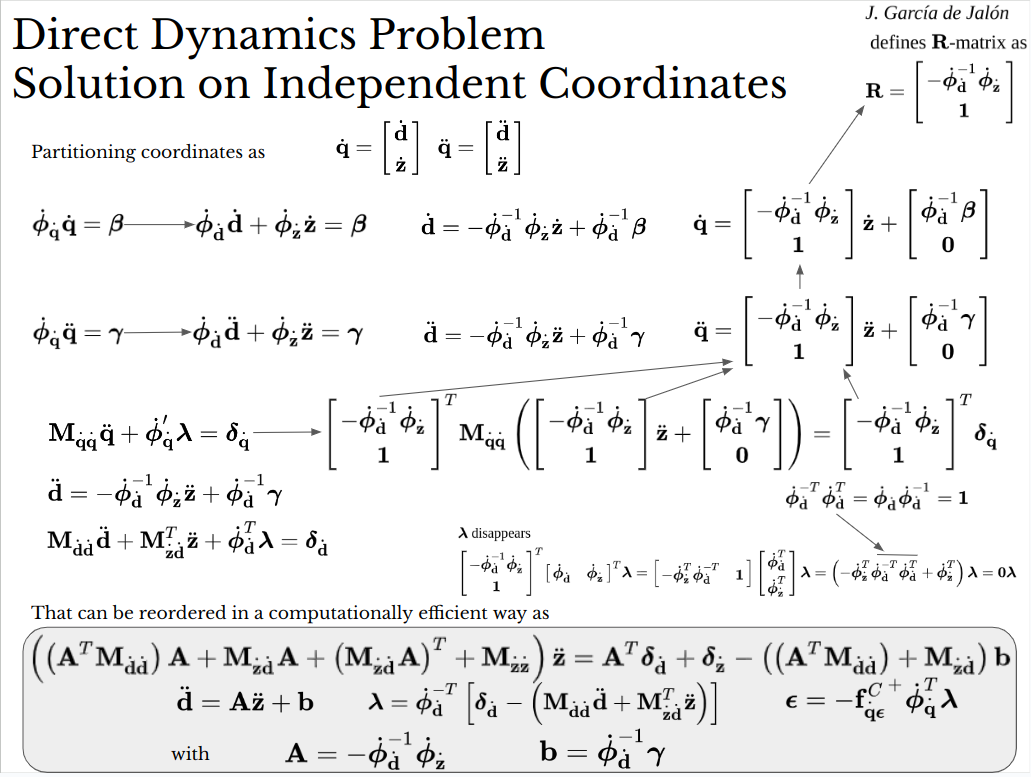

## Comented code:

Velocity partitioning is made based on LU decomposition. Permutation vector is used as an indirection operator to access "psicologically" ordered matrixes.

function [ddq_value,epsilon_value]=ddq_lambda_epsilon_from_Lagrange_dz(q_value, dq_value, t_value, param_value)

global lambda_value

%Determine a permutation perm, so that dq(permperm_dd_dz)=[dd;dz]
dPhi_dq_num=dPhi_dq_(q_value,t_value,param_value);
[L,U,perm_dd_dz] = lu(dPhi_dq_num','vector'); %[Q,R,perm_dd_dz] = qr(dPhi_dq_num,'vector');

%permutations for dependent and independent velocities
n_dd=rank(U); %n_dd=rank(R);

%Determine the dependent dd and independent dz jacobians using perm
perm_dd=perm_dd_dz(1:n_dd);
perm_dz=perm_dd_dz(n_dd+1:end);

%Determine the dependent dd and independent dz jacobians
dPhi_dd_num=dPhi_dq_num(:,perm_dd);
dPhi_dz_num=dPhi_dq_num(:,perm_dz);

%Determine the A and b matrixes
inv_dPhi_dd_num=pinv(dPhi_dd_num);
A=-inv_dPhi_dd_num * dPhi_dz_num;
b=inv_dPhi_dd_num*gamma_(q_value,dq_value,t_value,param_value);

%Determine submatrices
M_dqdq_num=M_qq_(q_value,t_value,param_value);
M_dddd_num=M_dqdq_num(perm_dd,perm_dd);
M_dzdd_num=M_dqdq_num(perm_dz,perm_dd);
M_dzdz_num=M_dqdq_num(perm_dz,perm_dz);
delta_q_num=delta_q_(q_value,dq_value,t_value,param_value);
delta_dd_num=delta_q_num(perm_dd,1);
delta_dz_num=delta_q_num(perm_dz,1);

%Assemble coeff_matrix and indep_term_vector
ATM_dddd=(M_dddd_num*A)';
M_dzddA=M_dzdd_num*A;

coeff_matrix=ATM_dddd*A+M_dzddA+M_dzddA'+M_dzdz_num;
indep_term_vector_b=A'*delta_dd_num+delta_dz_num-(ATM_dddd+M_dzdd_num)*b;

%Solve
ddz_value=pinv(coeff_matrix)*indep_term_vector_b;
ddd_value=A*ddz_value+b;

ddq_value(perm_dd_dz,1)=[ddd_value;
                         ddz_value];

lambda_value=inv_dPhi_dd_num'*(delta_dd_num-(M_dddd_num*ddd_value+M_dzdd_num'*ddz_value));

epsilon_value=pinv(-FC_qepsilon_(q_value,t_value,param_value))*dPhi_dq_num'*lambda_value;